# Coeficientes fourier

## Ejecicio a mano

## 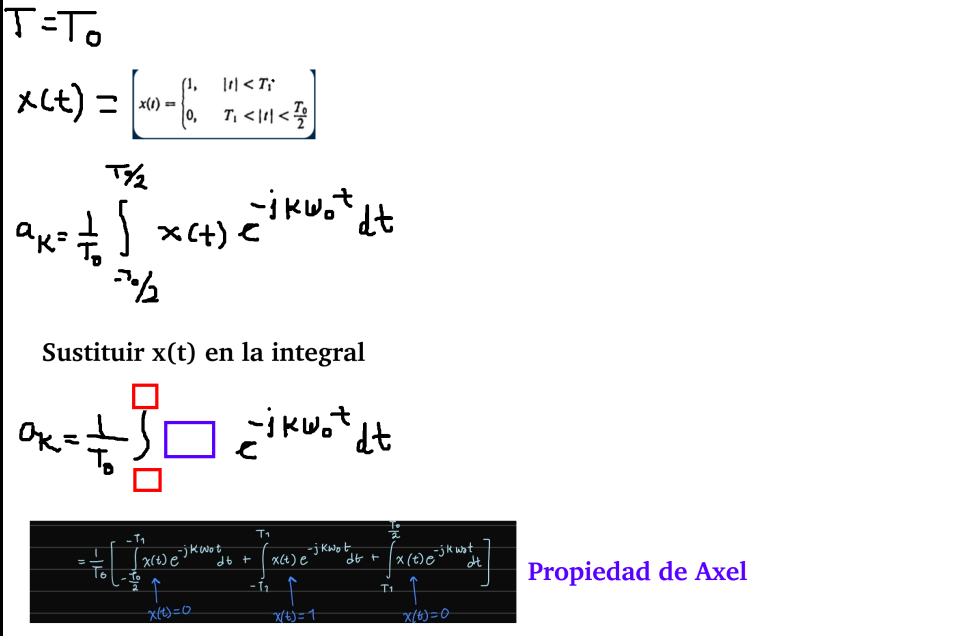

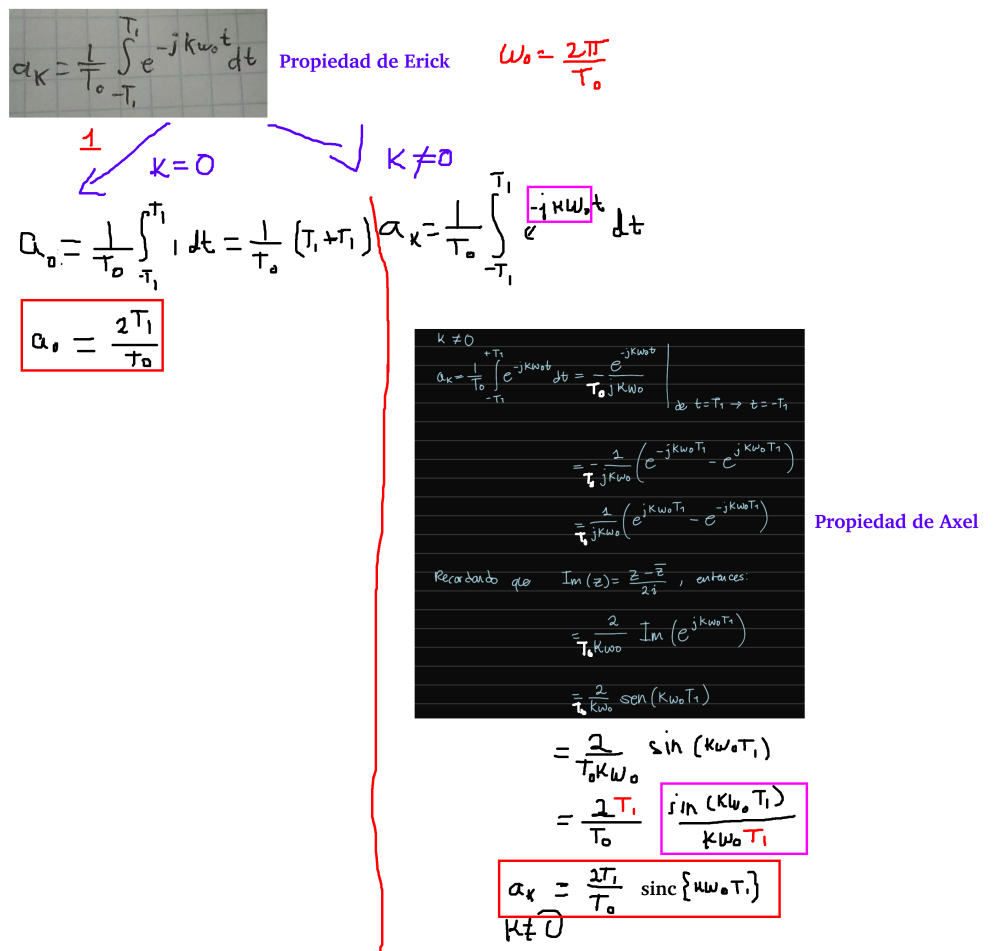

## Ploteo onda cuadrada

N=100;
k=-N:N;

A=8;
T0=2;
T1=T0/A;

w0=2*pi/T0;


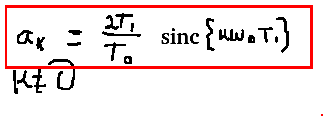

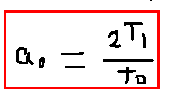

a_k=(2*T1/T0)*sinc(k*w0*T1);
a_0=2*T1/T0;

%La ecuación de a_k general no funciona
%Para k=0, por eso sustituimos un valor
%previamente calculado.
a_k(k==0)=a_0;

figure
stem(k,a_k)

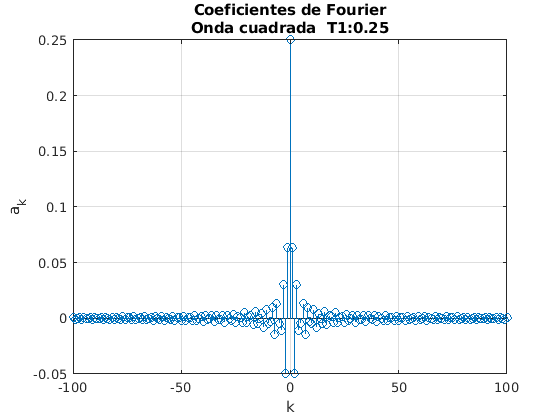

xlabel("k")
ylabel("a_k")
grid on
title(["Coeficientes de Fourier";"Onda cuadrada  T1:"+T1])

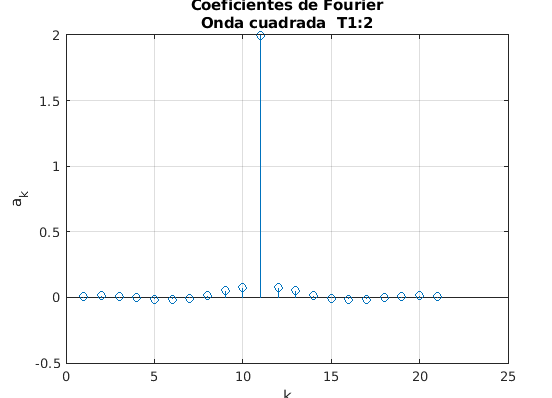 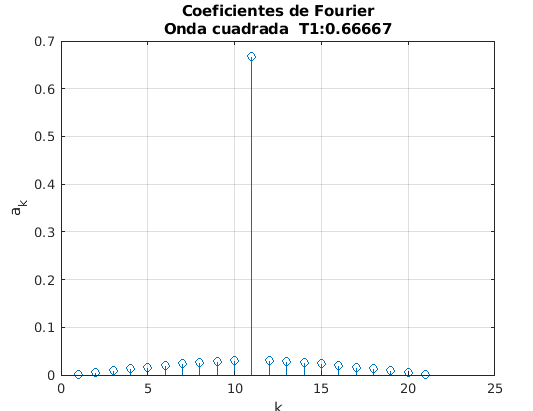

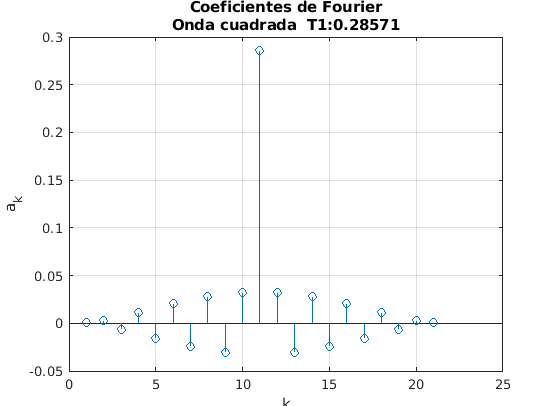

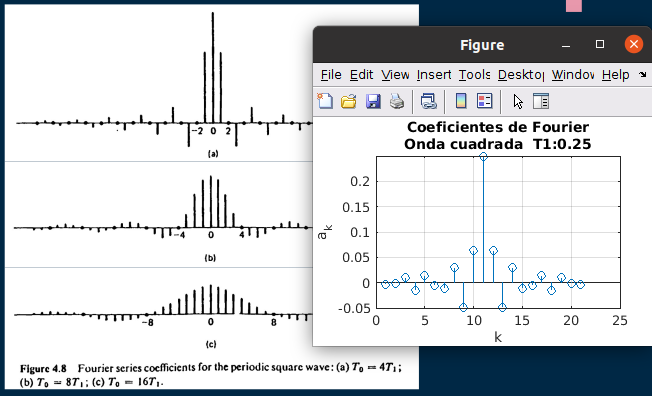

## Síntesis

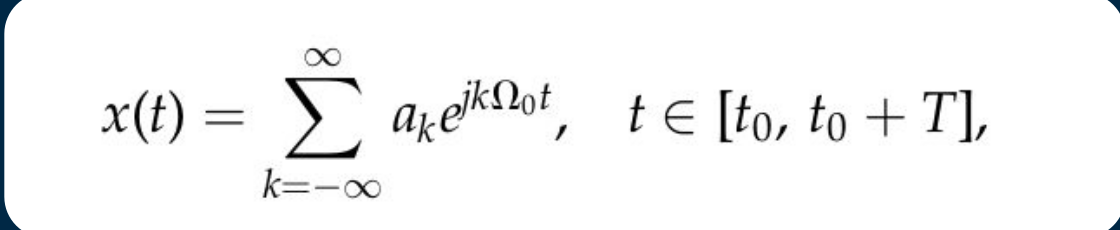

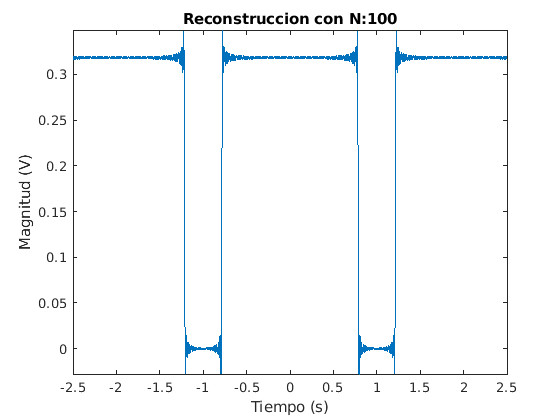

syms t
n=-3:3;
% %Numero de elementos
% numel()
% %Tamaño de la matriz en n X m
% size()
% %Tamaño más grande de la matriz 
% length()

x=sum(a_k.*exp(1i*k*w0*t));


figure
fplot(x,[-2.5 2.5])
xlabel("Tiempo (s)")
ylabel("Magnitud (V)")
title("Reconstruccion con N:"+N)

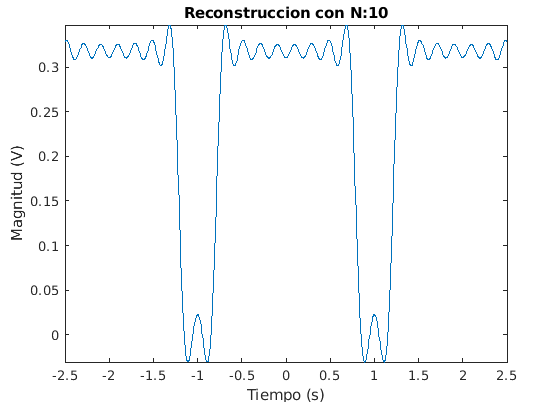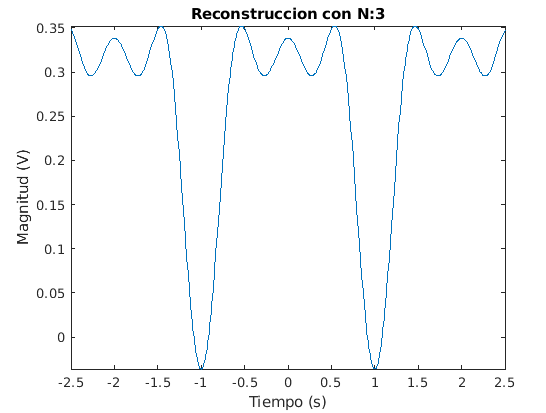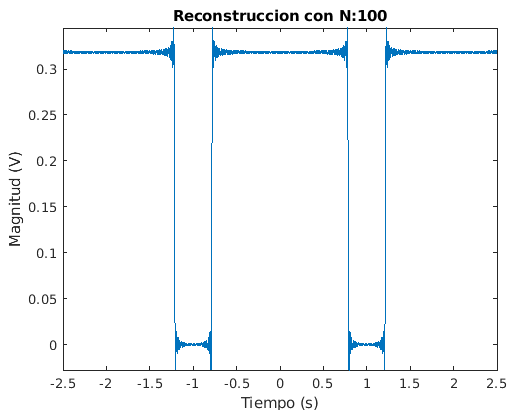

## Automatizacion de coeficientes

- Calcular la potencia del intervalo (Parseval)

- Calcular una integral de exponenciales complejas

- Generalizar la fórmula de cálculo

- Aprovechar ese loop para generar la base armónica

- Hacer una función que calule todos los coeficientes que uno pida

- Reconstruir 

clear
syms t
x=exp(-t);
t0=0;
tf=3;
T0=tf-t0;
w0=2*pi/T0;

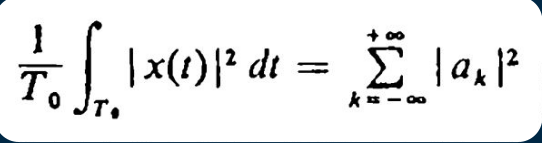

true=Decimales; false=Fracciones

%Potencia de la señal en el intervalo
P=(1/T0)*int(x^2,t0,tf)

$$P = \frac{1}{6}-\frac{{\mathrm{e}}^{-6}}{6}$$

P=double(P)

P = 0.1663

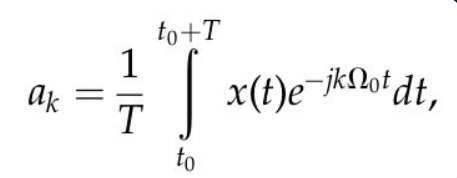

%Integral de un coeficiente
k=3;
ee_test=exp(-1i*k*w0*t);
a_test=(1/T0)*int(x*ee_test,t0,tf)

$$a\_test = -\frac{{\mathrm{e}}^{-3}\,\left({\mathrm{e}}^{3}-1\right)\,\mathrm{i}}{3\,\left(2\,\pi -\mathrm{i}\right)}$$

a_test=double(a_test)

a_test = 0.0078 - 0.0492i



%Generalizar calculo con ciclo for
N_rec=40;
k=-N_rec:N_rec;
[ee,a]=fcc(x,t0,T0,N_rec);

Coeficiente k=-40 
Coeficiente k=-39 
Coeficiente k=-38 
Coeficiente k=-37 
Coeficiente k=-36 
Coeficiente k=-35 
Coeficiente k=-34 
Coeficiente k=-33 
Coeficiente k=-32 
Coeficiente k=-31 
Coeficiente k=-30 
Coeficiente k=-29 
Coeficiente k=-28 
Coeficiente k=-27 
Coeficiente k=-26 
Coeficiente k=-25 
Coeficiente k=-24 
Coeficiente k=-23 
Coeficiente k=-22 
Coeficiente k=-21 
Coeficiente k=-20 
Coeficiente k=-19 
Coeficiente k=-18 
Coeficiente k=-17 
Coeficiente k=-16 
Coeficiente k=-15 
Coeficiente k=-14 
Coeficiente k=-13 
Coeficiente k=-12 
Coeficiente k=-11 
Coeficiente k=-10 
Coeficiente k=-9 
Coeficiente k=-8 
Coeficiente k=-7 
Coeficiente k=-6 
Coeficiente k=-5 
Coeficiente k=-4 
Coeficiente k=-3 
Coeficiente k=-2 
Coeficiente k=-1 
Coeficiente k=0 
Coeficiente k=1 
Coeficiente k=2 
Coeficiente k=3 
Coeficiente k=4 
Coeficiente k=5 
Coeficiente k=6 
Coeficiente k=7 
Coeficiente k=8 
Coeficiente k=9 
Coeficiente k=10 
Coeficiente k=11 
Coeficiente k=12 
Coeficiente k=13 
Coefici

## Reconstrucción

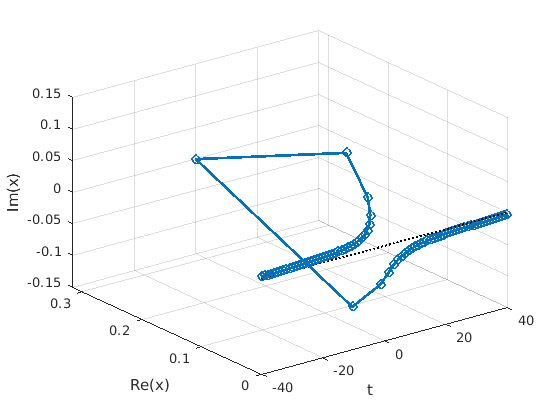

%Coeficientes
%Complex 3d
figure
complex3Dplot(k,a,[-N_rec N_rec])

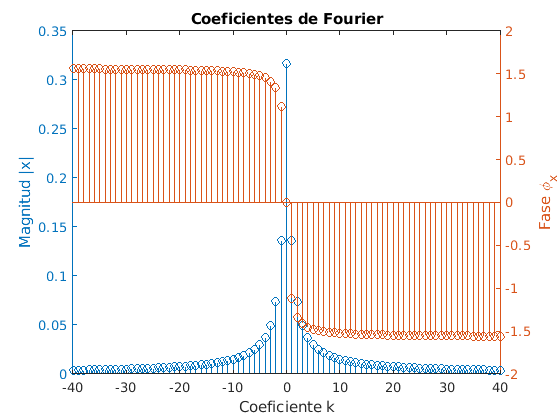

title("Coeficientes de Fourier")

%Real
figure
yyaxis left
stem(k,abs(a))
ylabel("Magnitud |x|")
yyaxis right
stem(k,angle(a))
ylabel("Fase \phi_x")
title("Coeficientes de Fourier")
xlabel("Coeficiente k")


%Reconstruccion
x_rec=sum(a.*ee);
figure
fplot([x x_rec],[0 5])
legend("Original","Reconstruccion")
 

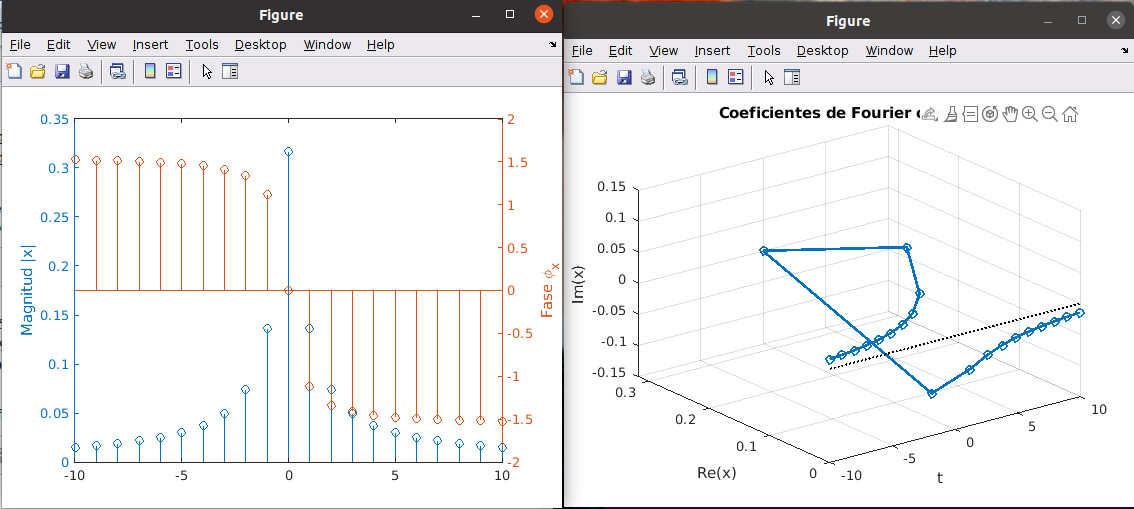

## Parseval

Eficiencia


$$\eta= \sum_{-\infty}^{+\infty} |a_k|^2 \ / \ P$$


eta=sum(abs(a).^2)/P

eta = 0.9932

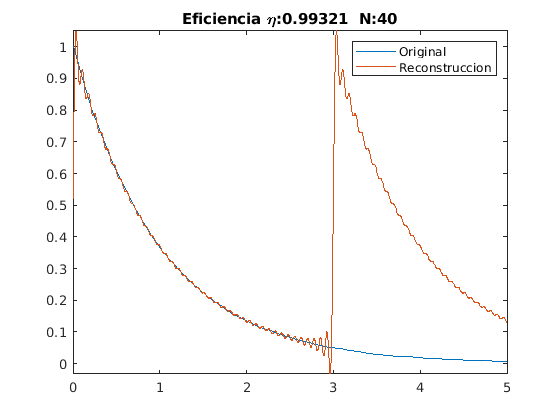

title("Eficiencia \eta:"+eta+"  N:"+N_rec)

- Utilizar las funciones para calcular trigonométricas y coseno

- Plotear los coeficientes

%Tarea moral


- Aproximar la función compleja

clear
syms t
%Visualizar función compleja
x=t^2+1i*2*pi*t

$$x = t^{2}+2\,\mathrm{i}\,\pi \,t$$

t0=0;
t1=10;
T0=t1-t0;
w0=2*pi/T0;
%Calcular coeficientes (5)
N=5;
k=-N:N;
[ee,a]=fcc(x,t0,T0,N);

Coeficiente k=-5 
Coeficiente k=-4 
Coeficiente k=-3 
Coeficiente k=-2 
Coeficiente k=-1 
Coeficiente k=0 
Coeficiente k=1 
Coeficiente k=2 
Coeficiente k=3 
Coeficiente k=4 
Coeficiente k=5 


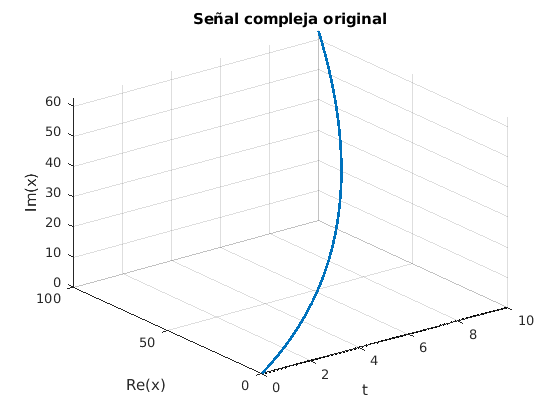

%Visualizar función compleja
figure
complex3Dplot(t,x,[t0 t1])
title("Señal compleja original")

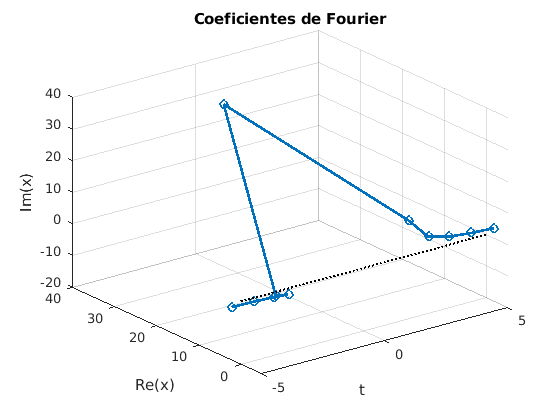

%Visualizar coeficientes 3D y magnitud fase
figure
complex3Dplot(k,a)
title("Coeficientes de Fourier")

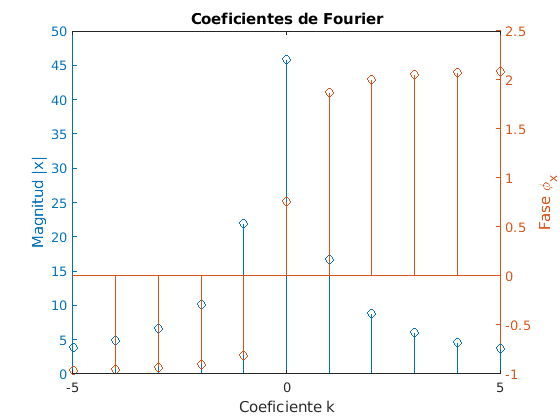


figure
yyaxis left
stem(k,abs(a))
ylabel("Magnitud |x|")
yyaxis right
stem(k,angle(a))
ylabel("Fase \phi_x")
xlabel("Coeficiente k")
title("Coeficientes de Fourier")



%Reconstrucción con eficiencia
P=(1/T0)*int(abs(x)^2,t0,t1)

$$P = \frac{400\,\pi^{2}}{3}+2000$$

P=double(P)

P = 3.3159e+03

P_a=sum(abs(a).^2)

P_a = 3.1877e+03

eta=P_a/P

eta = 0.9613

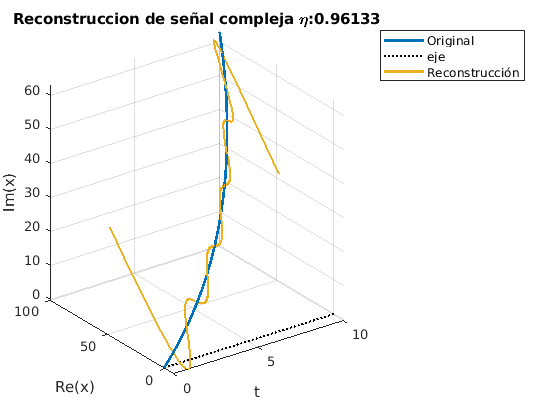


figure
complex3Dplot(t,x,[t0 t1])
hold on
complex3Dplot(t,sum(a.*ee),[t0 t1])
hold off
legend("Original","eje","Reconstrucción")
title("Reconstruccion de señal compleja \eta:"+eta)